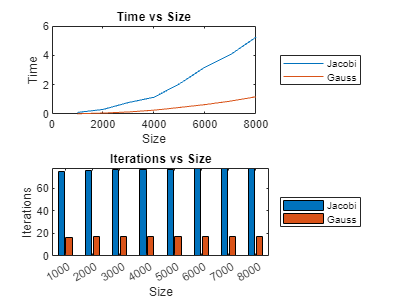

N = 1000:1000:8000;
n = length(N);
time_Jacobi = ones(1,n);
time_Gauss_Seidel = 2*ones(1,n);
iterations_Jacobi = 40*ones(1,n);
iterations_Gauss_Seidel = 40*ones(1,n);


for i = 1:n
    [A,b,M,bm,x,err_norm,time,iterations,index_number] = solve_Jacobi(N(i));
    time_Jacobi(i) = time;
    iterations_Jacobi(i) = iterations;
end


for i = 1:n
    [A,b,M,bm,x,err_norm,time,iterations,index_number] = solve_Gauss_Seidel(N(i));
    time_Gauss_Seidel(i) = time;
    iterations_Gauss_Seidel(i) = iterations;
end


plot_problem_5(N,time_Jacobi,time_Gauss_Seidel,iterations_Jacobi,iterations_Gauss_Seidel);